%EXERCISE 1: front-end simulator and signal analysis
% Luis Esteve NACC QP2026
% luis.esteve@upc.edu
% Javier Arribas NACC 2018
% jarribas@cttc.es
% Hyuk added script
clear all;
close all;
addpath('../../libs');

## DEFINE THE SIGNAL PARAMETERS

Sampling frequency and signal duration should be defined.

- Define the sampling frequency [Hz]

- sampling frequency should be higher than the central frequency;  Fs>2Fc

Fs=4e6;     % Fs: sampling frequency, DFLT 4 MHz

- Define the digitized signal duration [s]

Tsig=0.1;   % Tsig: signal duration, DFLT 0.1 sec

- Define the carrier frequency

             In order to not overload the MATLAB with high sampling frequency (GPS L1 1.5 GHz), we use here a low carrier frequency, e.g, 800 kHz.

Fc=800e3;   % Carrier frequency, DFLT 800 kHz

- Time vector for the generated signal

%generate the time vector
Ts=1/Fs;            % sampling period (sec)
t=0:Ts:(Tsig-Ts);   % time vector for signal (from 0 sec to Tsig, with the bin size of Ts)
Nsamples=length(t); % Number of samples

## Generate a BPSK baseband signal

Binary Phase Shift Keying (BPSK) implementation, [https://en.wikipedia.org/wiki/Phase-shift_keying](https://en.wikipedia.org/wiki/Phase-shift_keying) 

In Matlab default library, 'pskmod.m' can do it. 

initial_phase_rad=pi/4;     % phase offset


- BPSK symbol rate (How frequently symbol (0 or 1) changes per unit second

f_symbol_hz=1e3;    % BPSK symbol rate (Hz), DFLT 1 kHz

- Produce random symbols

bpsk_symbols=2*(rand(1,floor(f_symbol_hz*Tsig))>0.5)-1;
bpsk_symbols_resampled=resample(bpsk_symbols,Fs,f_symbol_hz,0); % To give a proper number of samples with Nsamples

s_bb_tx=bpsk_symbols_resampled*exp(1j*initial_phase_rad); % To give phase offset


- Perform the FFT

****** QUESTION 1 ****: **

**% Perform the FFT of s_bb_tx (baseband signal)  **

**% Check MATLAB FFT help by typing help FFT**

%S_bb_tx=?
S_bb_tx=fft(s_bb_tx); 


- Compute the frequency axis in Hz

f = Fs/2*linspace(-1,1,Nsamples);
%reorder the FFT results and compute the signal power spectrum in dBW/Hz
NFFT=Nsamples;
S_bb_tx_spectrum_db=10*log10((abs([S_bb_tx(floor((NFFT/2))+1:1:end) S_bb_tx(1:1:(NFFT/2))]).^2)/Nsamples);

% For the correction of the code (by H.PARK 2026-04-29)
S_bb_tx_spectrum_db_Corrected=10*log10((abs([S_bb_tx(floor((NFFT/2))+1:1:end) S_bb_tx(1:1:(NFFT/2))]).^2)/(Nsamples*Fs));


- Plot the spectrum

****** QUESTION 2 ****: **

**Capture a figure showing the spectrum of the BPSK signal from -3kHz to 3kHz. **

**Identify the main lobes and the secondary lobes of the modulation. **

**Which parameter of the BPSK modulation has an effect on the lobe spacing?**

**Check the effect by varying such parameter and perform the plot again.**

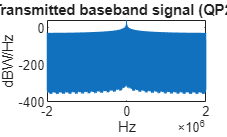

figure;
plot(f,S_bb_tx_spectrum_db);
title('Transmitted baseband signal (QP2026)');
xlabel('Hz');
ylabel('dBW/Hz');

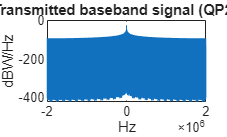


figure;
plot(f,S_bb_tx_spectrum_db_Corrected);
title('Transmitted baseband signal (QP2026)');
xlabel('Hz');
ylabel('dBW/Hz');

## Correction by HP 2026-04-29

It is neither PSD (Power Spectral Density) nor PS (Power Spectrum).

The current form is $$10 \log_{10} \left( \frac{|X[k]|^2}{N} \right)$$

For the PS (dBW), it should be $$\frac{|X[k]|^2}{N^2}$$

For the PSD (dBW/Hz), it should be PS/$\Delta f$,

 
$$$\Delta f = \frac{F_s}{N}$,  therefore  PSD = $\frac{|X[k]|^2 / N^2}{F_s / N} = \frac{|X[k]|^2}{N \cdot F_s}$$$


This definition is somewhat confused according to the definition of DFT/FFT.

For Signal processing (e.g., MATLAB, Python, C ...) 

- Amplitude: abs(fft(x)) / N

- PS: `(abs(fft(x)) / N)^2`

- `PSD: `(abs(fft(x))^2) / (N * Fs)

**Simple Code by using MATLAB Library functions**

## Generate a RF signal carrying the baseband signal

Notice the relation of the signal power of a sinusoid: power(s(t))= [s(t)]^2 -> a*cos(w)^2=(a^2/2)+(a^2/2)*cos(2w) average_power=avr((a^2/2)+(a^2/2)*cos(2w))=(a^2/2)


$$x(t) = A \cos(2\pi f_0 t + \theta)  \\

P = \frac{1}{T_0} \int_{0}^{T_0} |x(t)|^2 dt \\

P = \frac{1}{T_0} \int_{0}^{T_0} [A \cos(2\pi f_0 t + \theta)]^2 dt
P = \frac{A^2}{T_0} \int_{0}^{T_0} \cos^2(2\pi f_0 t + \theta) dt \\
 = \frac{A^2}{2T_0} \left[ t \right]_0^{T_0} = \frac{A^2}{2T_0} \cdot T_0 =  \frac{A^2}{2} \\

A = \sqrt{2 \cdot P}$$


%Define the RF signal power
Psig=5;

% **** QUESTION 3 ****: 

Write here the equation that produces an RF signal, modulating a carrier frequency Fc with the baseband signal s_bb_tx. Store it in a vector named s_rf_tx. The obtained signal must have a signal power equal to Psig.


$$$$s_{rf}(t) = \Re \left\{ A_{sig} \cdot s_{bb}(t) \cdot e^{j 2\pi F_c t} \right\}$$$$


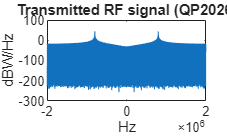

%Compute the signal amplitude
%Asig=?
Asig = sqrt(2*Psig);

%Compute the RF signal
%s_rf_tx=?
s_rf_tx = Asig * real(s_bb_tx .* exp(1j * 2 * pi * Fc * t));

% Perform the FFT
S_rf_tx=fft(s_rf_tx);
%compute the frequency axis in Hz
f = Fs/2*linspace(-1,1,Nsamples);
%reorder the FFT results and compute the signal power spectrum in dBW/Hz
NFFT=Nsamples;
S_rf_tx_spectrum_db=10*log10((abs([S_rf_tx(floor((NFFT/2))+1:1:end) S_rf_tx(1:1:(NFFT/2))]).^2)/Nsamples);
%plot the spectrum
figure;
plot(f,S_rf_tx_spectrum_db);
title('Transmitted RF signal (QP2026)');
xlabel('Hz');
ylabel('dBW/Hz');

% **** QUESTION 4 ****: 

% Capture the figure at maximum zoom out. Explain why it is symmetrical.

## Simulate the received signal and add noise

- Define a Doppler shift

Fd=4e3; % Doppler shift, DFLT 4 kHz


% **** QUESTION 5 ****: 

% Write here the equation that produces an RF received signal, modulating a

% carrier frequency Fc with the baseband signal s_bb_tx, and affected by a

% Doppler shift Fd. Store it in a vector named s_rf_rx. The obtained signal

% must have a signal power equal to Psig.

Received RF signal: $$s_{rf\_rx}(t) = \Re \left\{ A_{sig} \cdot s_{bb\_tx}(t) \cdot e^{j 2\pi (F_c + F_d) t} \right\}$$


%s_rf_rx=?
s_rf_rx = Asig * real(s_bb_tx .* exp(1j * 2 * pi * (Fc + Fd) * t));


- add noise: Noise is defined by SNR

SNR_dB=3;
SNR_lin=10^(SNR_dB/10);


% **** QUESTION 6 ****: 

% Compute the noise amplitude (linear)  $$P_{noise} = \frac{P_{sig}}{SNR_{lin}}$$, AWGN: 0 mean, 1 variance (power)

therefore noise power $P_{noise} = A_n^{2} $

%An=?
An = sqrt(Psig / SNR_lin); %An : noise amplitude

- Noise filtering: 

 WHY DO WE FILTER THE NOISE? (Band-limiting the AWGN)

1. Hardware Realism: Real RF receiver front-ends have physical filters. They process "band-limited noise", not infinite white noise

2. Anti-Aliasing: Prevents out-of-band high-frequency noise from  folding back (aliasing) into our signal band during ADC sampling.

3. Precise SNR Control: Ensures the calculated noise power is distributed strictly within the effective bandwidth, maintaining the exact target SNR (e.g., 3dB) in the simulation.

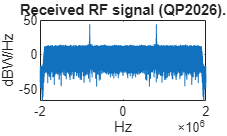

noise=An*randn(1,Nsamples);
RF_BW_Hz=Fs/2.1;
[b,a] = butter(5,RF_BW_Hz/(Fs/2),'low');
noise=filtfilt(b,a,noise);
y_rf_rx=s_rf_rx+noise;

% Perform the FFT
Y_rf_rx=fft(y_rf_rx);
%compute the frequency axis in Hz
f = Fs/2*linspace(-1,1,Nsamples);
%reorder the FFT results and compute the signal power spectrum in dBW/Hz
NFFT=Nsamples;
Y_rf_rx_spectrum_db=10*log10((abs([Y_rf_rx(floor((NFFT/2))+1:1:end) Y_rf_rx(1:1:(NFFT/2))]).^2)/Nsamples);
%plot the spectrum
figure;
plot(f,Y_rf_rx_spectrum_db);
title('Received RF signal (QP2026).');
xlabel('Hz');
ylabel('dBW/Hz');


% **** QUESTION 7 ****: 
% Capture the figure at maximum zoom out. Explain the effects of noise.

% **** QUESTION 8 ****: 
% Perform a zoom in and measure the approximated center frequency 
% of the received signal.

## SNR, CN0 estimation

 QUESTION 9 : Compute the SNR and the CNO in dB 

HINT: Consider RF_BW_Hz=Fs/2. 

HINT: Remember that the signal and noise power can be estimated by using the autocorrelation estimation Rxx=(1/K)*(x*x'), where x is a vector containing the signal or noise samples.

$$C/N_0 = \frac{Signal\_Power}{Noise\_Density} = \frac{Signal\_Power}{Total\_Noise / Bandwidth} = SNR \times Bandwidth$$ (dB-Hz)


$$$CN_0 (dB) = SNR (dB) + 10\log_{10}(BW)$$$


%SNR_estim_dB=?
P_sig_estim = (1/Nsamples) * (s_rf_rx * s_rf_rx');
P_noise_estim = (1/Nsamples) * (noise * noise');
SNR_estim_lin = P_sig_estim / P_noise_estim;
SNR_estim_dB = 10 * log10(SNR_estim_lin);

disp(['Estimated SNR is ' num2str(SNR_estim_dB) ' vs. desired SNR: ' num2str(SNR_dB) ' [dB]']);

Estimated SNR is 3.2221 vs. desired SNR: 3 [dB]



%CN0_estim_dB=?
RF_BW_Hz = Fs / 2; 
CN0_estim_dB = SNR_estim_dB + 10 * log10(RF_BW_Hz);

disp(['Estimated CN0 is ' num2str(CN0_estim_dB) ' [dBHz]']);

Estimated CN0 is 66.2324 [dBHz]


## Downconvert the RF signal to baseband

design the LPF filters

BB_BW_Hz=Fc/2;
[b,a] = butter(5,BB_BW_Hz/(Fs/2),'low');

% **** QUESTION 10 ****: 

% Perform the downconversion and IQ demodulation, considering

% the expected carrier frequency Fc. Store the baseband signal in s_bb_rx

% HINT: The Low Pass Filter (LPF) can be applied by using

% y=filtfilt(b,a,x), where x is the input signal vector and y is the filtered

% output signal vector.


$$$$\cos(2\pi F_c t) \cdot \cos(2\pi F_c t) = \frac{1}{2} + \frac{1}{2}\cos(4\pi F_c t)$$$$



%y_bb_rx_I_filt=?
%y_bb_rx_Q_filt=?
mixer_I = y_rf_rx .* cos(2*pi*Fc*t);
mixer_Q = y_rf_rx .* -sin(2*pi*Fc*t);

y_bb_rx_I_filt = filtfilt(b, a, mixer_I) * (2 / Asig);
y_bb_rx_Q_filt = filtfilt(b, a, mixer_Q) * (2 / Asig);

%ensamble the recovered baseband signal (complex envelope)
y_bb_rx=y_bb_rx_I_filt+1j*y_bb_rx_Q_filt;

% Perform the FFT
Y_bb_rx=fft(y_bb_rx);
%plot the spectrum magnitude
%compute the frequency axis in Hz
f = Fs/2*linspace(-1,1,Nsamples);
%reorder the FFT results and compute the signal power spectrum in dBW/Hz
NFFT=Nsamples;
Y_bb_rx_spectrum_db=10*log10((abs([Y_bb_rx(floor((NFFT/2))+1:1:end) Y_bb_rx(1:1:(NFFT/2))]).^2)/Nsamples);
figure;


% **** QUESTION 11 ****: 

% Capture the received baseband signal spectrum figure. Estimate

% the approximated LPF filter bandwidth and estimate the approximated BPSK signal bandwidth

% Explain how to calculate both bandwidths, the one of the filter and the one of the received BPSK signal

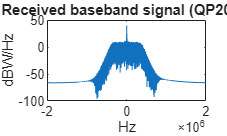


plot(f,Y_bb_rx_spectrum_db);
title('Received baseband signal (QP2026)');
xlabel('Hz');
ylabel('dBW/Hz');